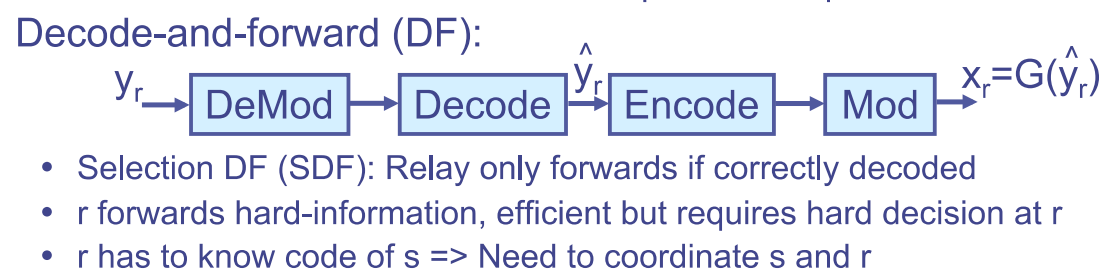

clear;
n = 10^5;
% For QPSK
bits_per_symbol = 2; 
% Number of symbols 
N = n/bits_per_symbol;
% Powers of source and relays
Pt = 1;
Ps = Pt/3; 
Pr1 = Pt/3;
Pr2 = Pt/3;
% SNR
SNR_db = [1:25];
% the following code provides symbols for QPSK

hMod  = comm.QPSKModulator('BitInput', true);
hDemod  = comm.QPSKDemodulator('BitOutput', true);
hConEnc  = comm.ConvolutionalEncoder;
hDec  = comm.ViterbiDecoder('InputFormat','Hard');
hError  = comm.ErrorRate('ComputationDelay',3,'ReceiveDelay', 34);

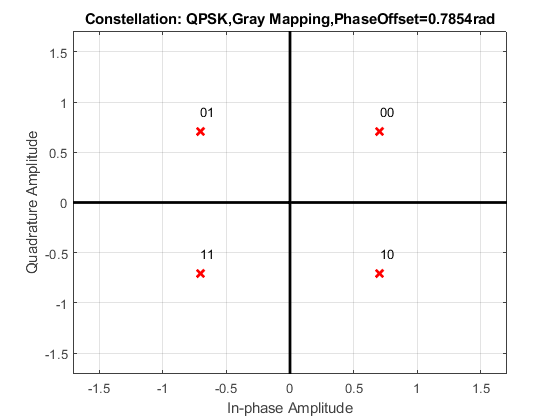

constellation(hMod)

SNR = db2pow(SNR_db);
BER = zeros(1, length(SNR));
BER_AFR1 = zeros(1, length(SNR));
BER_DFR1 = zeros(1, length(SNR));
for i=1:length(SNR)
    hChan_S_D = comm.AWGNChannel('NoiseMethod', ...
                             'Signal to noise ratio (SNR)',...
                             'SNR',SNR(i));
    hChan_S_R1 = comm.AWGNChannel('NoiseMethod', ...
                             'Signal to noise ratio (SNR)',...
                             'SNR',SNR(i));
    hChan_S_R2 = comm.AWGNChannel('NoiseMethod', ...
                             'Signal to noise ratio (SNR)',...
                             'SNR',SNR(i));
    hChan_R1_D = comm.AWGNChannel('NoiseMethod', ...
                             'Signal to noise ratio (SNR)',...
                             'SNR',SNR(i));
    hChan_R2_D = comm.AWGNChannel('NoiseMethod', ...
                             'Signal to noise ratio (SNR)',...
                             'SNR',SNR(i));
    % S > D
    data = randi([0 1],n,1);
    encodedData = step(hConEnc, data);
    modSignal = step(hMod, encodedData);
    receivedSignal = step(hChan_S_D, modSignal);
    demodSignal = step(hDemod, receivedSignal);
    receivedBits = step(hDec, demodSignal);
    errors = step(hError, data, receivedBits);
    BER(i) = errors(1); 
    
    % S > R1 > D
    encodedData = step(hConEnc, data);
    modSignal = step(hMod, encodedData);    
    receivedSignal_R1 = step(hChan_S_R1, modSignal);
    amplifiedSignal_R1= 2*receivedSignal_R1;
    receivedSignal = step(hChan_R1_D, amplifiedSignal_R1);
    demodSignal = step(hDemod, receivedSignal);
    receivedBits = step(hDec, demodSignal);
    errors = step(hError, data, receivedBits);
    BER_AFR1(i) = errors(1); 
    
    % S > R1 > D [DF]
    encodedData = step(hConEnc, data);
    modSignal = step(hMod, encodedData);    
    receivedSignal_R1 = step(hChan_S_R1, modSignal);
    demodSignal_R1 = step(hDemod, receivedSignal_R1);
    receivedBits_R1 = step(hDec, demodSignal_R1);  
    encodedData_R1 = step(hConEnc, receivedBits_R1);
    modSignal_R1 = step(hMod, encodedData_R1); 
    receivedSignal = step(hChan_R1_D, modSignal_R1);
    demodSignal = step(hDemod, receivedSignal);
    receivedBits = step(hDec, demodSignal);
    errors = step(hError, data, receivedBits);
    BER_DFR1(i) = errors(1); 
end

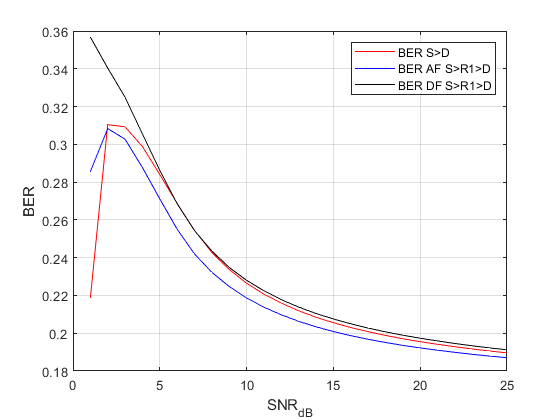

figure(), hold on, grid on, box on
plot(SNR_db, BER, 'r');
plot(SNR_db, BER_AFR1, 'b');
plot(SNR_db, BER_DFR1, 'k');
xlabel("SNR_d_B"); ylabel("BER");
legend("BER S>D", "BER AF S>R1>D", "BER DF S>R1>D")